clear;
clc;
%%1a
T=1;
sample_y = cell(1,3);
sample_mean_y = cell(1,3);
sample_cov_y = cell(1,3);
y_hat_ekf = cell(1,3);
y_hat_ukf = cell(1,3);
y_hat_ckf = cell(1,3);
P_y_ekf = cell(1,3);
P_y_ukf = cell(1,3);
P_y_ckf = cell(1,3);

for choice = 1:3
    switch choice
        case 1
            mean_x = [125; 125];
            cov_x = [10^2 0; 0 5^2];
        case 2
            mean_x = [-25; 125];
            cov_x = [10^2 0; 0 5^2];
        case 3
            mean_x = [60; 60];
            cov_x = [10^2 0; 0 5^2];
        otherwise
            error('Invalid scenario index');
    end

    % Dual bearing measurement model parameters
    s1 = [0; 100];
    s2 = [100; 0];
    noise_std = 0.1*pi/180;
    cov_r = diag([noise_std^2 noise_std^2]);

    % Set the number of samples
    numSamples = 10000;

    % Initialize variables for storing samples and calculating statistics
    samples_y = zeros(2, numSamples);

    % Loop over the number of samples
    for i = 1:numSamples
        % Sample the state vector x from the state density
        x = mvnrnd(mean_x, cov_x)';
        
        % Compute the dual bearing measurement vector y using the state vector x
        [y,~] = dualBearingMeasurement(x, s1, s2);
        
        % Add random sample noise to the measurement vector y
        y = y + mvnrnd(zeros(2, 1), cov_r)';
        
        % Store the sample measurement vector y
        samples_y(:, i) = y;
    end
    sample_y{choice} = samples_y;
    sample_mean_y{choice} = mean(samples_y, 2);
    disp(['Sample mean for case ', num2str(choice)]);
    disp(sample_mean_y{choice});
    sample_cov_y{choice} = cov(samples_y');
    disp(['Sample covariance for case ', num2str(choice)]);
    disp(sample_cov_y{choice});

%%1b
h = @(x) dualBearingMeasurement(x, s1, s2);
[ y , ~ ] = dualBearingMeasurement (x, s1, s2);

[y_hat_ekf{choice}, P_y_ekf{choice}] = MeanCovarianceY(mean_x, cov_x, y, h, cov_r, 'EKF');
[y_hat_ukf{choice}, P_y_ukf{choice}] = MeanCovarianceY(mean_x, cov_x, y, h, cov_r, 'UKF');
[y_hat_ckf{choice}, P_y_ckf{choice}] = MeanCovarianceY(mean_x, cov_x, y, h, cov_r, 'CKF');
end 

Sample mean for case 1


    0.1985
    1.3747



Sample covariance for case 1


    0.0017    0.0014
    0.0014    0.0059



Sample mean for case 2


    2.3268
    2.3549



Sample covariance for case 2


    0.0561    0.0104
    0.0104    0.0020



Sample mean for case 3


   -0.5954
    2.1528



Sample covariance for case 3


    0.0099   -0.0113
   -0.0113    0.0152



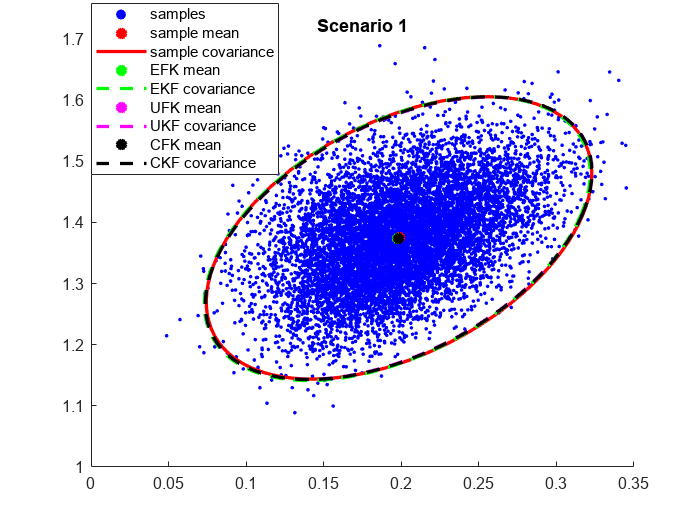


[xy1] = sigmaEllipse2D(sample_mean_y{1}, sample_cov_y{1},3,100);
[xy2] = sigmaEllipse2D(sample_mean_y{2}, sample_cov_y{2},3,100);
[xy3] = sigmaEllipse2D(sample_mean_y{3}, sample_cov_y{3},3,100);

figure; clf; hold on;
hold on;
scatter(sample_y{1}(1,:),sample_y{1}(2,:),5,'b','filled');%sample
plot(sample_mean_y{1}(1,:),sample_mean_y{1}(2,:),'*r','Linewidth',4);%mean
plot(xy1(1,:),xy1(2,:),'-r','Linewidth',2);%covariance for 1

plot(y_hat_ekf{1}(1,:),y_hat_ekf{1}(2,:),'*g','LineWidth',4)
temp = sigmaEllipse2D(y_hat_ekf{1}, P_y_ekf{1},3,100);
plot(temp(1,:),temp(2,:),'--g','Linewidth',2);

plot(y_hat_ukf{1}(1,:),y_hat_ukf{1}(2,:),'*m','LineWidth',4)
temp = sigmaEllipse2D(y_hat_ukf{1}, P_y_ukf{1},3,100);
plot(temp(1,:),temp(2,:),'--m','Linewidth',2);

plot(y_hat_ckf{1}(1,:),y_hat_ckf{1}(2,:),'*k','LineWidth',4)
temp = sigmaEllipse2D(y_hat_ckf{1}, P_y_ckf{1},3,100);
plot(temp(1,:),temp(2,:),'--k','Linewidth',2);

legend('samples','sample mean','sample covariance','EFK mean', 'EKF covariance','UFK mean', 'UKF covariance','CFK mean', 'CKF covariance')

title('Scenario 1')

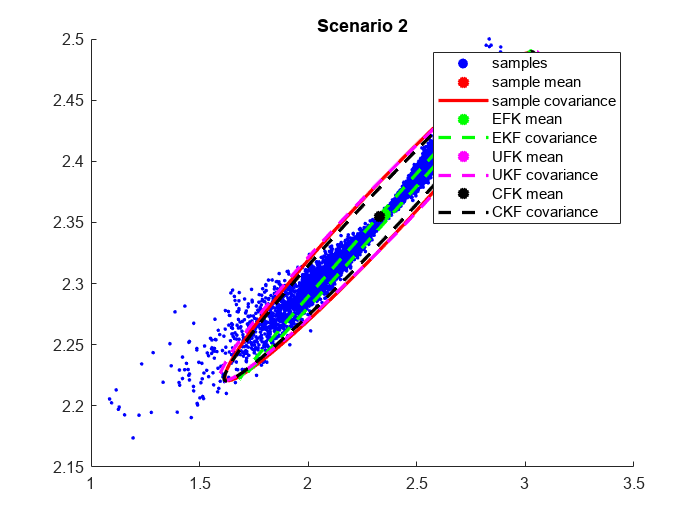


figure; clf; hold on;
hold on;
scatter(sample_y{2}(1,:),sample_y{2}(2,:),5,'b','filled');%sample
plot(sample_mean_y{2}(1,:),sample_mean_y{2}(2,:),'*r','Linewidth',4);%mean
plot(xy2(1,:),xy2(2,:),'-r','Linewidth',2);%covariance for 1

plot(y_hat_ekf{2}(1,:),y_hat_ekf{2}(2,:),'*g','LineWidth',4)
temp = sigmaEllipse2D(y_hat_ekf{2}, P_y_ekf{2},3,100);
plot(temp(1,:),temp(2,:),'--g','Linewidth',2);

plot(y_hat_ukf{2}(1,:),y_hat_ukf{2}(2,:),'*m','LineWidth',4)
temp = sigmaEllipse2D(y_hat_ukf{2}, P_y_ukf{2},3,100);
plot(temp(1,:),temp(2,:),'--m','Linewidth',2);

plot(y_hat_ckf{2}(1,:),y_hat_ckf{2}(2,:),'*k','LineWidth',4)
temp = sigmaEllipse2D(y_hat_ckf{2}, P_y_ckf{2},3,100);
plot(temp(1,:),temp(2,:),'--k','Linewidth',2);

legend('samples','sample mean','sample covariance','EFK mean', 'EKF covariance','UFK mean', 'UKF covariance','CFK mean', 'CKF covariance')

title('Scenario 2')

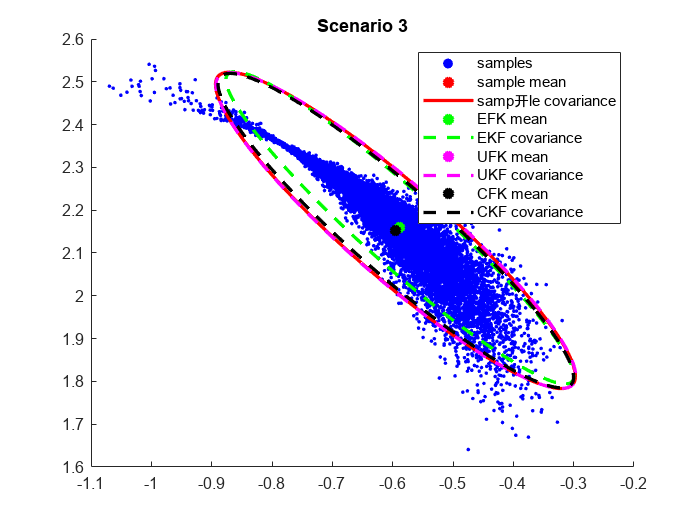


figure; clf; hold on;
hold on;
scatter(sample_y{3}(1,:),sample_y{3}(2,:),5,'b','filled');%sample
plot(sample_mean_y{3}(1,:),sample_mean_y{3}(2,:),'*r','Linewidth',4);%mean
plot(xy3(1,:),xy3(2,:),'-r','Linewidth',2);%covariance for 1

plot(y_hat_ekf{3}(1,:),y_hat_ekf{3}(2,:),'*g','LineWidth',4)
temp = sigmaEllipse2D(y_hat_ekf{3}, P_y_ekf{3},3,100);
plot(temp(1,:),temp(2,:),'--g','Linewidth',2);

plot(y_hat_ukf{3}(1,:),y_hat_ukf{3}(2,:),'*m','LineWidth',4)
temp = sigmaEllipse2D(y_hat_ukf{3}, P_y_ukf{3},3,100);
plot(temp(1,:),temp(2,:),'--m','Linewidth',2);

plot(y_hat_ckf{3}(1,:),y_hat_ckf{3}(2,:),'*k','LineWidth',4)
temp = sigmaEllipse2D(y_hat_ckf{3}, P_y_ckf{3},3,100);
plot(temp(1,:),temp(2,:),'--k','Linewidth',2);

legend('samples','sample mean','samp开le covariance','EFK mean', 'EKF covariance','UFK mean', 'UKF covariance','CFK mean', 'CKF covariance')

title('Scenario 3')